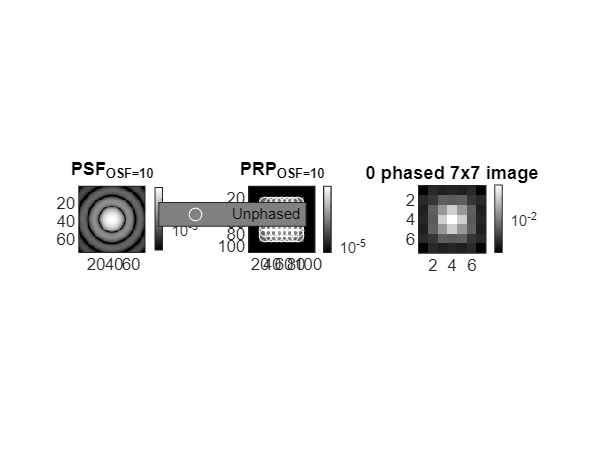

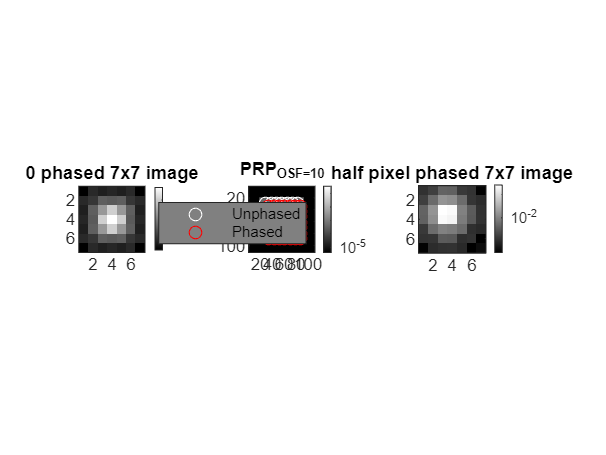

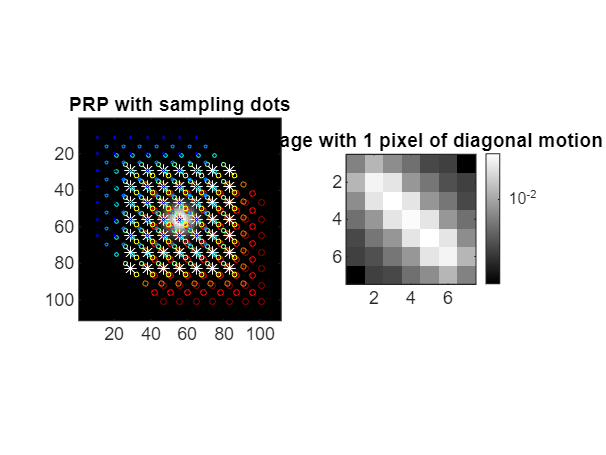

a = 0

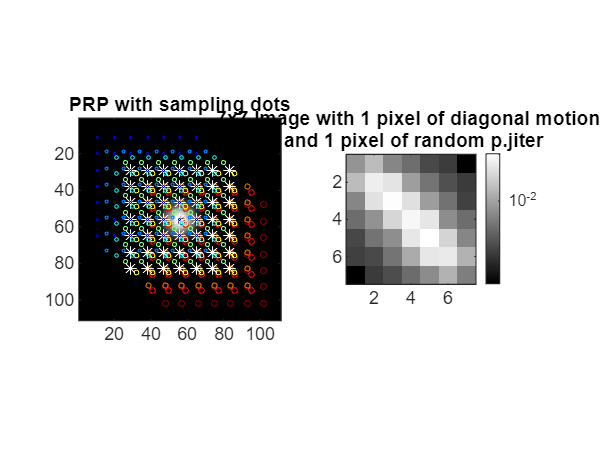

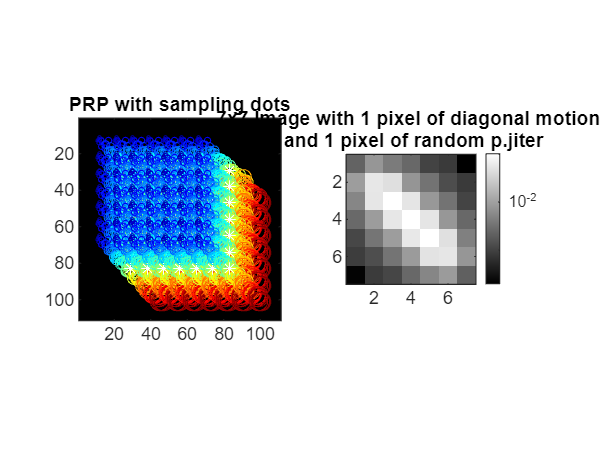

p.fl    = 1;      %[m] focal length
p.dApp  = 0.075;      %[m] Apperture Diameter
p.p     = 5e-6;     %[m] pixel pitch
p.cnt   = 1e3;      %[#] sqrt of number of pixels
p.rate  = [3,50];   %[hz] frame rate of imagery
p.int   = [5e-2,5e-3];%[s] integration time
p.well  = 20000;    %[electrons] well depth
p.osf   = 9;       %keep odd
p.rTgt  = 100e3;
p.dTgt  = 5;
p.sV    = [0,0,1];
p.mot   = [1,1]*2;
p.jit   = 1;
p.motSam= 15;

[psf, x, y] = diffraction_psf(1e-6, 20, 5e-7);
prp = conv2(psf/sum(psf(:)),ones(p.osf),'same');
prp = padarray(prp,p.mot*p.osf);
sam = round(size(prp,1)/2)+[-3:3]*p.osf;
im = prp(sam,sam);

if 1
%static prp
if 1
    figure
cmap = gray(256);
subplot(1,3,1)
imagesc(psf); axis equal; axis tight;
colorbar; set(gca,"ColorScale","log")
title("PSF_{OSF=10}")
subplot(1,3,2)
imagesc(prp); axis equal; axis tight; hold on;
colorbar; set(gca,"ColorScale","log")
title("PRP_{OSF=10}")
[a,b]=meshgrid(sam);
scatter(a(:),b(:),'w')
lh = legend({'Unphased','Phased'}); set( lh, 'Box', 'on', 'Color',[.5 .5 .5] );
subplot(1,3,3)
imagesc(im); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("0 phased 7x7 image")
colormap(cmap)
end

%phasing
if 1
    figure
subplot(1,3,1)
imagesc(prp(sam,sam)); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("0 phased 7x7 image")
colormap(cmap)
subplot(1,3,2)
imagesc(prp); axis equal; axis tight; hold on;
colorbar; set(gca,"ColorScale","log")
title("PRP_{OSF=10}")
[a,b]=meshgrid(sam);
scatter(a(:),b(:),'w');
scatter(a(:)+5,b(:)+5,'r');
lh = legend({'Unphased','Phased'}); set( lh, 'Box', 'on', 'Color',[.5 .5 .5]);
subplot(1,3,3)
imagesc(prp(sam+5,sam+5)); axis equal; axis tight;
colorbar; set(gca,"ColorScale","log");
title("half pixel phased 7x7 image");
colormap(cmap);
end

%Linear
lin1 = round(linspace(-p.mot(1),p.mot(1),p.motsam)*p.osf);
lin2 = round(linspace(-p.mot(2),p.mot(2),p.motsam)*p.osf);
for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+lin1; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+lin2; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        imM(i,j) = mean(prp(sub2ind(size(prp),sam1,sam2)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on;
c = jet(length(lin1)); a = 0;
for i = 1:length(sam)
    for j = 1:length(sam)
        scatter(sam(i)+lin1,sam(j)+lin2,[1:length(lin1)],c); hold on
        scatter(sam(i),sam(j),'w*')
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imM); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("7x7 Image with 1 pixel of diagonal motion")
colormap(cmap)

%Linear + p.jiter
jitX = round(normrnd(lin1,p.jit));
jitY = round(normrnd(lin2,p.jit));
for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        imJ(i,j) = mean(prp(sub2ind(size(prp),sam1,sam2)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on;
a = 0
for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        scatter(sam1,sam2,[1:length(sam1)],c); hold on
        scatter(sam(i),sam(j),'w*')
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imJ); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title(sprintf("7x7 Image with 1 pixel of diagonal motion \n and 1 pixel of random p.jiter"))
colormap(cmap)



%Linear + p.jiter super sampled
lin1 = round(linspace(-p.mot(1),p.mot(1),p.motsam*10)*p.osf);
lin2 = round(linspace(-p.mot(2),p.mot(2),p.motsam*10)*p.osf);
jitX = round(normrnd(lin1,p.jit));
jitY = round(normrnd(lin2,p.jit));
for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        imJ(i,j) = mean(prp(sub2ind(size(prp),sam1,sam2)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on;
c = jet(length(sam1)); a = 0;
for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        scatter(sam1,sam2,[1:length(sam1)],c); hold on
        scatter(sam(i),sam(j),'w*');
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imJ); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title(sprintf("7x7 Image with 1 pixel of diagonal motion \n and 1 pixel of random p.jiter"))
colormap(cmap)
end

## Target Stuff

[im,N] = sphereIm(p,0,'Odd') 

im =          0         0         0    0.0096    0.0822    0.1237    0.0822    0.0096         0         0         0
         0         0    0.1127    0.3941    0.5393    0.5774    0.5393    0.3941    0.1127         0         0
         0    0.1127    0.4973    0.6772    0.7633    0.7899    0.7633    0.6772    0.4973    0.1127         0
    0.0096    0.3941    0.6772    0.8155    0.8879    0.9107    0.8879    0.8155    0.6772    0.3941    0.0096
    0.0822    0.5393    0.7633    0.8879    0.9546    0.9759    0.9546    0.8879    0.7633    0.5393    0.0822
    0.1237    0.5774    0.7899    0.9107    0.9759    0.9843    0.9759    0.9107    0.7899    0.5774    0.1237
    0.0822    0.5393    0.7633    0.8879    0.9546    0.9759    0.9546    0.8879    0.7633    0.5393    0.0822
    0.0096    0.3941    0.6772    0.8155    0.8879    0.9107    0.8879    0.8155    0.6772    0.3941    0.0096
         0    0.1127    0.4973    0.6772    0.7633    0.7899    0.7633    0.6772    0.4973    0.1127       

N =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

prpTgt = conv2(N,prp./p.osf^2);
I = (p.osf-1):p.osf:(size(prpTgt,1)-p.osf+1);
J = I;

Imot = (linspace(0,p.mot(1),p.motSam)-p.mot(1)/2)*p.osf;
Jmot = (linspace(0,p.mot(2),p.motSam)-p.mot(2)/2)*p.osf;

jitX = round(normrnd(Imot,p.jit*p.osf));
jitY = round(normrnd(Jmot,p.jit*p.osf));

sz = size(prpTgt);
for i = 1:length(I)
    for j = 1:length(J)
        sami = I(i)+jitX; sami(sami<1) = 1; sami(sami>sz(1)) = sz(1);
        samj = J(j)+jitY; samj(samj<1) = 1; samj(samj>sz(2)) = sz(2);  
        idx = sub2ind(sz,sami,samj);
        IM(i,j) = mean(prpTgt(idx));
    end
end
figure
cmap = gray(256);
subplot(1,3,1)
imagesc(im); axis equal; axis tight;
colorbar; set(gca,"ColorScale","log")
title('Geometric Spherical Target Image')
subplot(1,3,2)
imagesc(prpTgt); axis equal; axis tight;
colorbar; set(gca,"ColorScale","log")
title('Target PRP');  hold on
c = jet(length(sami))

c =          0         0    0.7500
         0         0    1.0000
         0    0.2500    1.0000
         0    0.5000    1.0000
         0    0.7500    1.0000
         0    1.0000    1.0000
    0.2500    1.0000    0.7500
    0.5000    1.0000    0.5000
    0.7500    1.0000    0.2500
    1.0000    1.0000         0


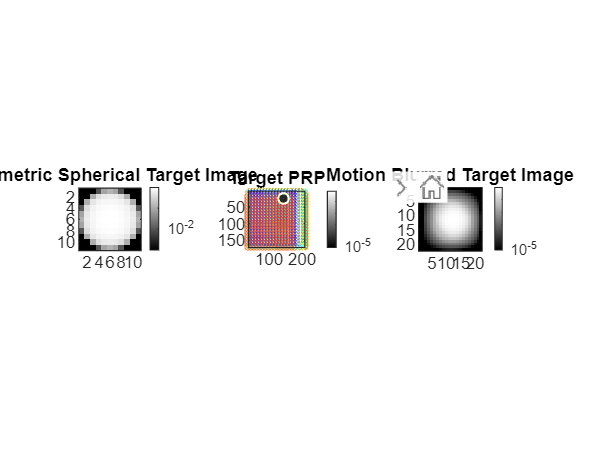

for i = 1:length(I)
    for j = 1:length(J)
        sami = I(i)+jitX; sami(sami<1) = 1; sami(sami>sz(1)) = sz(1);
        samj = J(j)+jitY; samj(samj<1) = 1; samj(samj>sz(2)) = sz(2);  
        scatter(sami,samj,[1:length(sami)],c,'MarkerEdgeAlpha',0.5); hold on
        scatter(I(i),I(j),'w*');
    end
end
subplot(1,3,3)
imagesc(IM); axis equal; axis tight;
colorbar; set(gca,"ColorScale","log")
title('Motion Blurred Target Image')
colormap(cmap)

## functions

% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end

function [im,N] = sphereIm(p,plotTF,EvenOrOddOrIgnore) 
    % Sample SPhere
    IFOV = atan(p.p/p.fl);
    tgtAng = atan(p.dTgt/p.rTgt);
    tgtPix=tgtAng/IFOV; %How many pixels the target subtends
    if tgtPix<1 %if it is a subpixel target just use the phase equation
        ang = acos(dot([0,0,1],p.sV));
        F = 2/3/pi^2*((pi-ang)*cos(ang)+sin(ang));
        if strcmp(EvenOrOddOrIgnore,'Even')
            im = [1,1;1,1]*.25*F;
        else
            im = F;
        end
    else    
        phs = 0; %This term is used to help us ensure even or odd images
        if mod(ceil(tgtPix),2)==1 && strcmp(EvenOrOddOrIgnore,'Even')
            phs = 1;
        elseif mod(ceil(tgtPix),2)==0 && strcmp(EvenOrOddOrIgnore,'Odd')
            phs = 1;
        end
        sams = ceil(tgtAng/IFOV+phs)*p.osf;  %How many pixels we'll use to sample
        scl=sams/(tgtPix*p.osf); %We need to scale up our radial sampling to account for the sphere not filling the entire thing.
         
         
        % Here we are going to create 2D theta and phi LUTs to get samples of a
        % sphere
         
         
        % Create 2D direction vectors for a square to calculate Phi
        [X,Y] = meshgrid(linspace(-scl,scl,sams),linspace(-scl,scl,sams));
        R = sqrt(X.^2+Y.^2);
        phi = acos(dot(cat(3,X./R,Y./R),repmat(cat(3,1,0),[size(X),1]),3));
        phi(end/2+1:end,:)=2*pi-phi(end/2+1:end,:);
         
         
        %use the radial image to calculate theta
        theta = pi/2-abs(acos(R));
         
         
        % For each subpixel sample, map it to a unit vector on the sphere.
        V = cat(3,sin(theta).*cos(phi),sin(phi).*sin(theta),cos(theta));
        msk = R; msk(R<1)=1; msk(R>1)=nan;
        V=V.*repmat(msk,[1,1,3]);
         
        %Calc dot of normal with the sun 
        N=dot(V,repmat(reshape(p.sV,[1,1,3]),[size(R),1]),3)/norm(p.sV);
        N(N<0)=0;
        N(isnan(N))=0;
         
        %Downsample
        
        for i = 1:ceil(tgtPix+phs)
            for j = 1:ceil(tgtPix+phs)
                im(i,j)=sum(N([1:p.osf]+p.osf*(i-1),[1:p.osf]+p.osf*(j-1)),"all")/p.osf^2;
            end
        end   
    end
     
    if plotTF
        figure
        subplot(1,3,1)
        imagesc(V(:,:,1)); title('x'); colorbar
        subplot(1,3,2)
        imagesc(V(:,:,2)); title('y'); colorbar
        subplot(1,3,3)
        imagesc(V(:,:,3)); title('z'); colorbar
        
        figure
        R2 = sqrt(sum(V.^2,3));
        imagesc(R2); title('R (to make sure its all 1)')
        
        figure
        subplot(1,2,1)
        imagesc(N); colorbar
        subplot(1,2,2)
        imagesc(im); colorbar
    end 
end
